# **Modeling the Underwater Environment**

*Last updated: 4/15/2021*

3D visualizations provide a excellent resource for demonstrating capabilities and functions of a design project to cross-functional teams and interested parties. Additionally, we can leverage these detailed environments to provide more realistic sensor feedback to the plant model and control systems from these environments. Access to more more intricate or complex environment data may reveal additional design limitations or issues early, allowing for engineers to more easily address them. 

We can assemble a 3D environment which allows for us to visualize the model performance inside a rendering and simulation tool such as:

- Simulink 3D Animation

- Unreal Engine 4

In this case, we will focus on Unreal Engine 4 in tandem with MATLAB R2020b, and I will provide a link to an example of constructing an environment from heightmap data in Simulink 3D Animation. The toolboxes required for each section are listed, and the cumulative list of toolboxes is

### Simulation Performance Disclaimer:

Unreal Engine is a graphics-intensive program, and the simulation speed may be greatly impacted by the quality of the device used to execute the simulation. A plethora of optimization options are available through the Unreal Engine Editor in addition to those which I point out in RoadRunner. 

However, the easiest and simplest way to improve performance is by commenting out the Lidar sensor and LIDAR Visualization MATLAB function block ' or by reducing the resolution of the [Simulation 3d Camera Get block](matlab:web(fullfile(docroot, 'vdynblks/ref/simulation3dcameraget.html'))). This should enable you to visualize the scene in this demonstration on most devices. 

## Create and Prepare the Scene for Desired 3D Visualization Suite

There are several options for Simulation 3D software and each one requires a slightly different approach to creating the environment. 

#### Gather and Format Data

We first need to Gather heightmap data for your region of interest (ROI). In this case, we are interested in bathymetry data. These datasets often come as NetCDF files, and I obtained the data for the example from the [NOAA Website](https://maps.ngdc.noaa.gov/viewers/bathymetry/). The data contained in the NetCDF file can be directly read into matlab with the [ncread](matlab:web(fullfile(docroot,'matlab/ref/ncread.html'))) tool. 


      ncfile = 'bathymetryData.nc';
      % read latitude and longitude
      lat = ncread(ncfile,'lat');
      lon = ncread(ncfile,'lon');
      
      % Read elevation data
      Elevation = ncread(ncfile,'Band1')';
      Elevation = Elevation';
      
      % Create raster reference object
      RasterRef = georasterref('RasterSize',size(Elevation),'LatitudeLimits',[min(lat),max(lat)],........
          'LongitudeLimits',[min(lon),max(lon)]);
      
      % Write GeoTIFF File (With Mapping Toolbox)
      % geotiffwrite('bathymetryData.tiff',Elevation,RasterRef)


If we want to bring this data into RoadRunner and export it for Unreal Engine, it is necessary to convert the format to GeoTIFF (or a similarly [compatible](https://www.mathworks.com/help/releases/R2020b/roadrunner/GIS-Assets.html) format). **MATLAB Mapping Toolbox** provides the [geotiffwrite](matlab:web(fullfile(docroot,'/map/ref/geotiffwrite.html'))) function which makes this operation easier. 

### For Sim3D Animation 

You may read the terrain data directly into Simulink 3D Animation as a heightmap. A detailed example exists:

[https://www.mathworks.com/help/releases/R2020b/sl3d/examples/terrain-visualization.html](https://www.mathworks.com/help/releases/R2020b/sl3d/examples/terrain-visualization.html)

which should guide you through this process. 

### For Unreal Engine 

To simulate a custom underwater scene in Unreal Engine, there are two options:

- Create the environment by-hand (either directly in Unreal Engine 4) or via an external 3D modeling tool such as Blender, Maya, or 3DS Max. 

- Generate a scene with RoadRunner.

#### By-hand:

If you are creating terrain directly in Unreal Engine 4, you may refer to their [Terrain Tool and 'Sculpting' documentation](https://docs.unrealengine.com/en-US/BuildingWorlds/Landscape/Editing/SculptMode/index.html). This should be a solid starting point for creating some 'realistic-looking' terrain. For more details regarding accurate terrain generation from Data outside of RoadRunner, please please refer to other traditional 3D modeling softwares along with their respective documentation, tutorials, and resources. 

#### **From RoadRunner**

We can import the GIS data we converted to GeoTIFF earlier using the RoadRunner [Library Browser](https://www.mathworks.com/help/releases/R2020b/roadrunner/ug/Library-Browser.html). Once we have the height-map data in the Library Browser, we can add it to our Scene using the [Elevation Map Tool](https://www.mathworks.com/help/releases/R2020b/roadrunner/ug/Elevation-Map-Tool.html). 

Once the hieghtmap is placed, we can move the Scene Workspace and World Origin around to the location we desire with the [World Settings Tool](https://www.mathworks.com/help/releases/R2020b/roadrunner/ug/World-Settings-Tool.html). When we have the area of interest selected, we can outline the region of interest using the [Terrain Tools](https://www.mathworks.com/help/releases/R2020b/roadrunner/Terrain-Tools.html?s_tid=CRUX_lftnav), specifically the [Surface Tool](https://www.mathworks.com/help/releases/R2020b/roadrunner/ug/Surface-Tool.html), and apply 'Sand' as the material from the 'materials' folder in the Library Browser.     

Once we have the surface created and the material is as-desired, we can use the [Prop Tools](https://www.mathworks.com/help/releases/R2020b/roadrunner/Prop-Tools.html) in RoadRunner to add things like Rocks to our underwater landscape. 

In **R2021a **onward, we can make optimizations such as adding [Levels of Detail](https://www.mathworks.com/help/releases/R2021a/roadrunner/ug/customize-levels-of-detail-in-exported-scenes.html) to the exported scene.   

Finally, we can [export](https://www.mathworks.com/help/releases/R2020b/roadrunner/ug/Exporting-to-Unreal.html) from RoadRunner to Unreal Engine, or any one of the listed [export formats](https://www.mathworks.com/help/roadrunner/Exporting.html). 

## Customizing the Scene in Unreal Engine

Once your scene is imported into Unreal Engine, you can lean on the tools provided by the Unreal 4 Editor to make changes to the scene. There are some detailed instructions for [scene customization](matlab:web(fullfile(docroot, 'vdynblks/ug/customize-3d-scenes-for-vehicle-dynamics-simulations.html'))) in our documentation. Just make sure you have the correct Unreal Engine version, for this example we are using MATLAB R2020b and the supported Unreal Engine version is 4.23.  

In the example provided, I have added an ocean water surface in addition to a "Post Process Volume" which will tint the underwater portion of our scene blue. To replicate the ocean surface, you may use a 'Plane' 3D object or the 'Landscape' tool to create a flat, grey surface. Then, apply a texture to it. I created a custom 'ocean' texture which uses a few tricks to animate waves and some water effects. However, this does degrade performance. For a much simpler solution, just apply a translucent 'blue' texture or leave the surface out entirely.  

Then you can drag a "Post Process Volume" into the scene and modify it. In order to make this volume fit the scene, you may either search the details pane and check the box labeled "Infinite Extent (Unbound)" or change the 'scale' X, Y, and Z values until the volume entirely encompases the portion of your scene which is underwater.  

The Infinite Extent option will apply the volume to the entire level. If you are manually fitting the volume using the 'Scale', I recommend setting volume Transformation position at [0 0 0] first. Then, change the Z position of the volume and leverage the scale to make sure that your volume covers everything below the X-Y plane all the way to the ocean floor. 

Once your volume is fitted correectly, we can modify the details of the volume to make the environment look like we're underwater. Below are the settings I used to create the blue tint in my scene. 

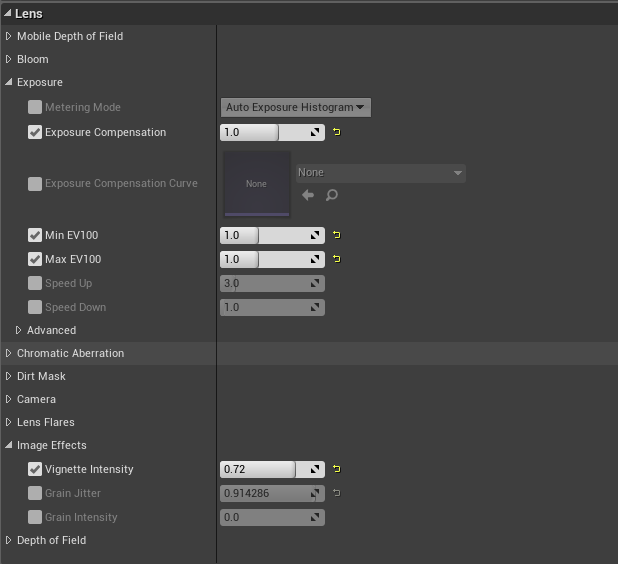  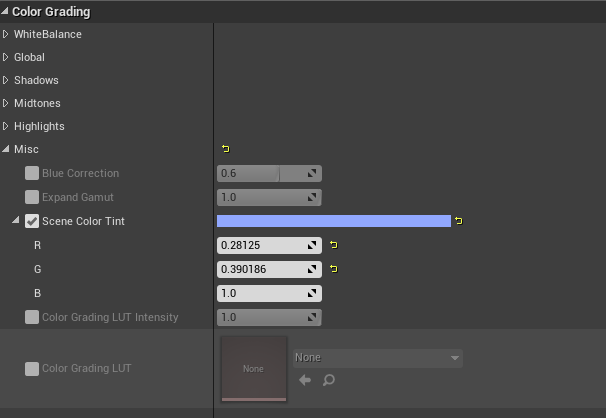

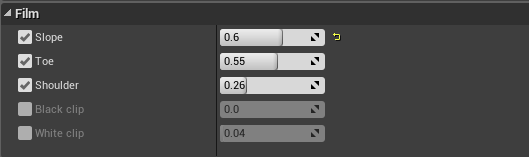  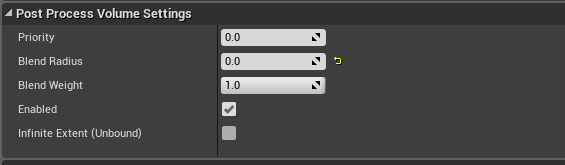

# Connect Environment and  Actors to Simulink

First, add the plugin to your Unreal Engine project and enable it. There is a four part process outlined for setting up your Unreal to Simulink connection. The first part covers [installation of the support package and environment configuraiton](matlab:web(fullfile(docroot, 'vdynblks/ug/install-support-package-and-configure-environment.html'))).

Following all 4 parts of that process should enable you to interface with Simulink. Now, open the simulink model: 

open_system('AUV_UE4_Visualization');

When you want to open your Unreal Project, use the 'Open Unreal Editor' button inside the block parameters of the 'Simulation  3D Scene Configuration' block. 

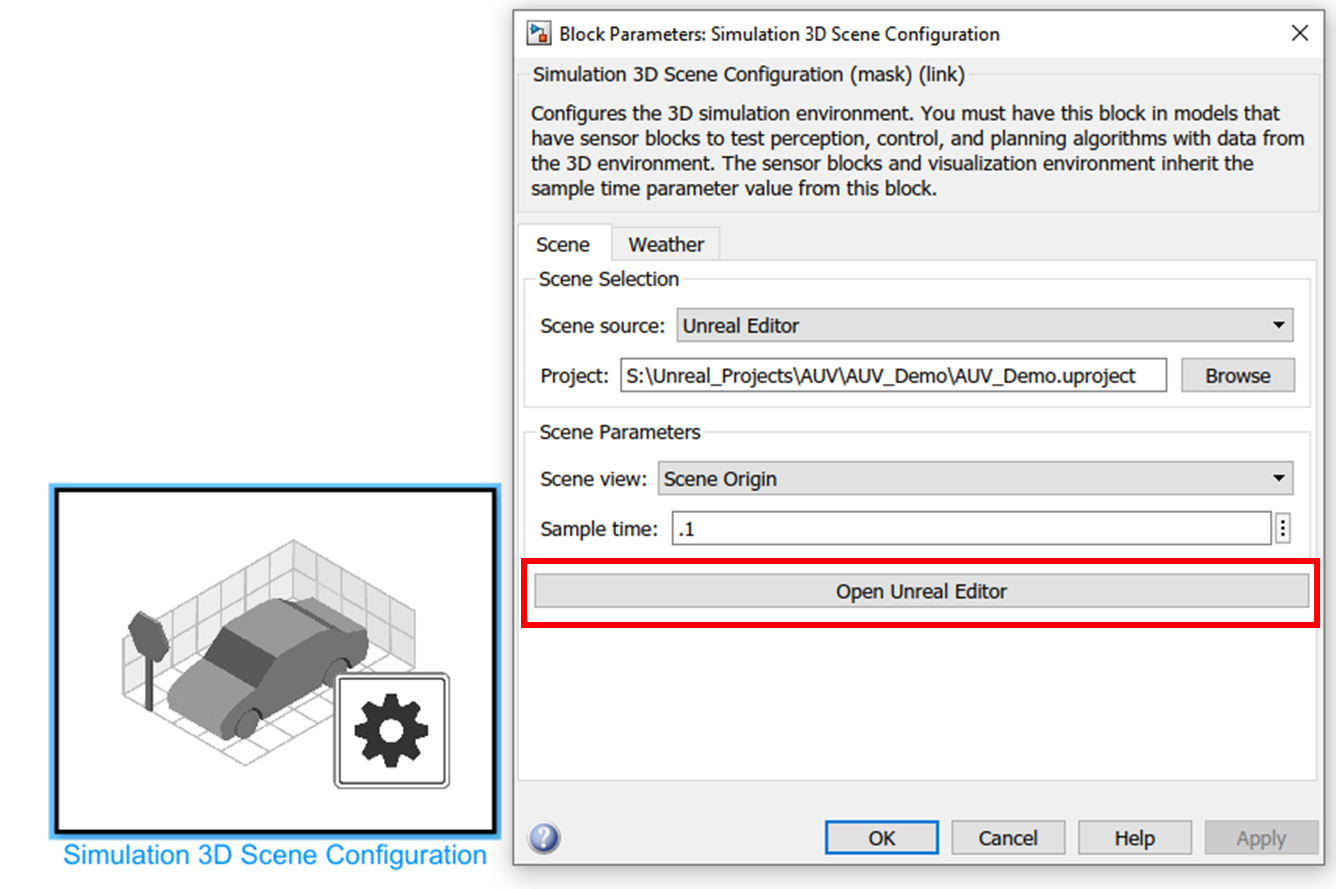

With the plugin enabled, you can add custom actors by finding the Sim3dActor object in the content browser in Unreal Engine. Make sure you  enable Developer, Engine, and Plugin content in the content browser. 

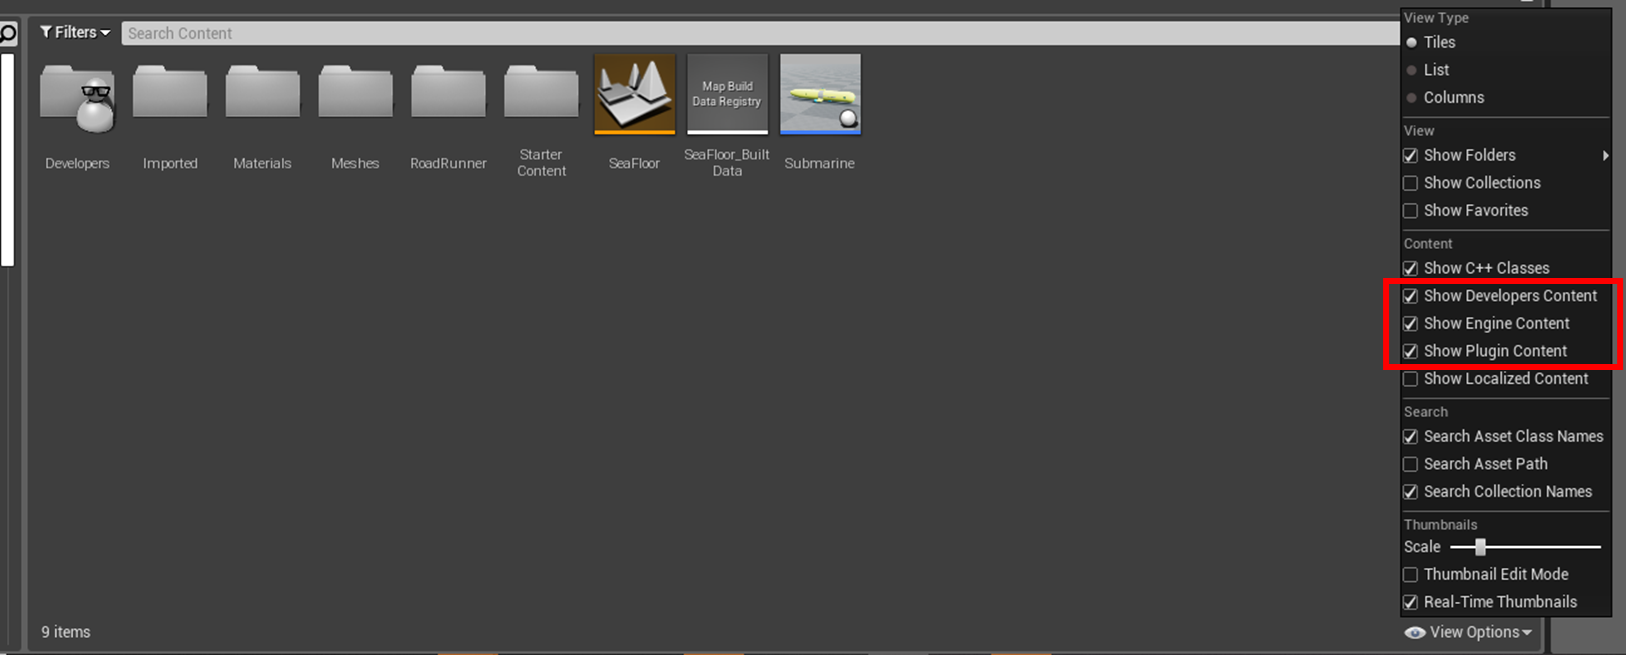

You can now right-click Sim3dActor, and create a Blueprint class based on this actor type:

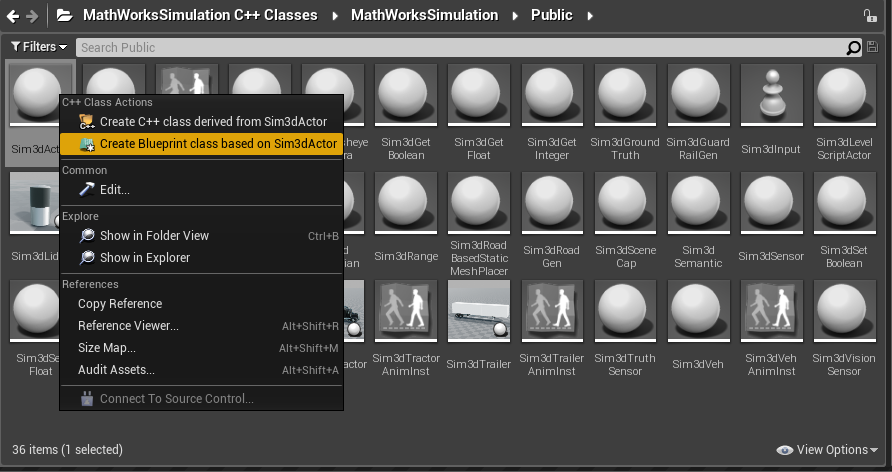

The actor you created should be aviable in the content browser. Editing it will enable you to supply your own custom model to a Simulink-controlled actor. FIrst, click the 'Add Component' button and select 'static mesh' from the drop-down menu. Then, supply the desired static mesh on the right-hand side. 

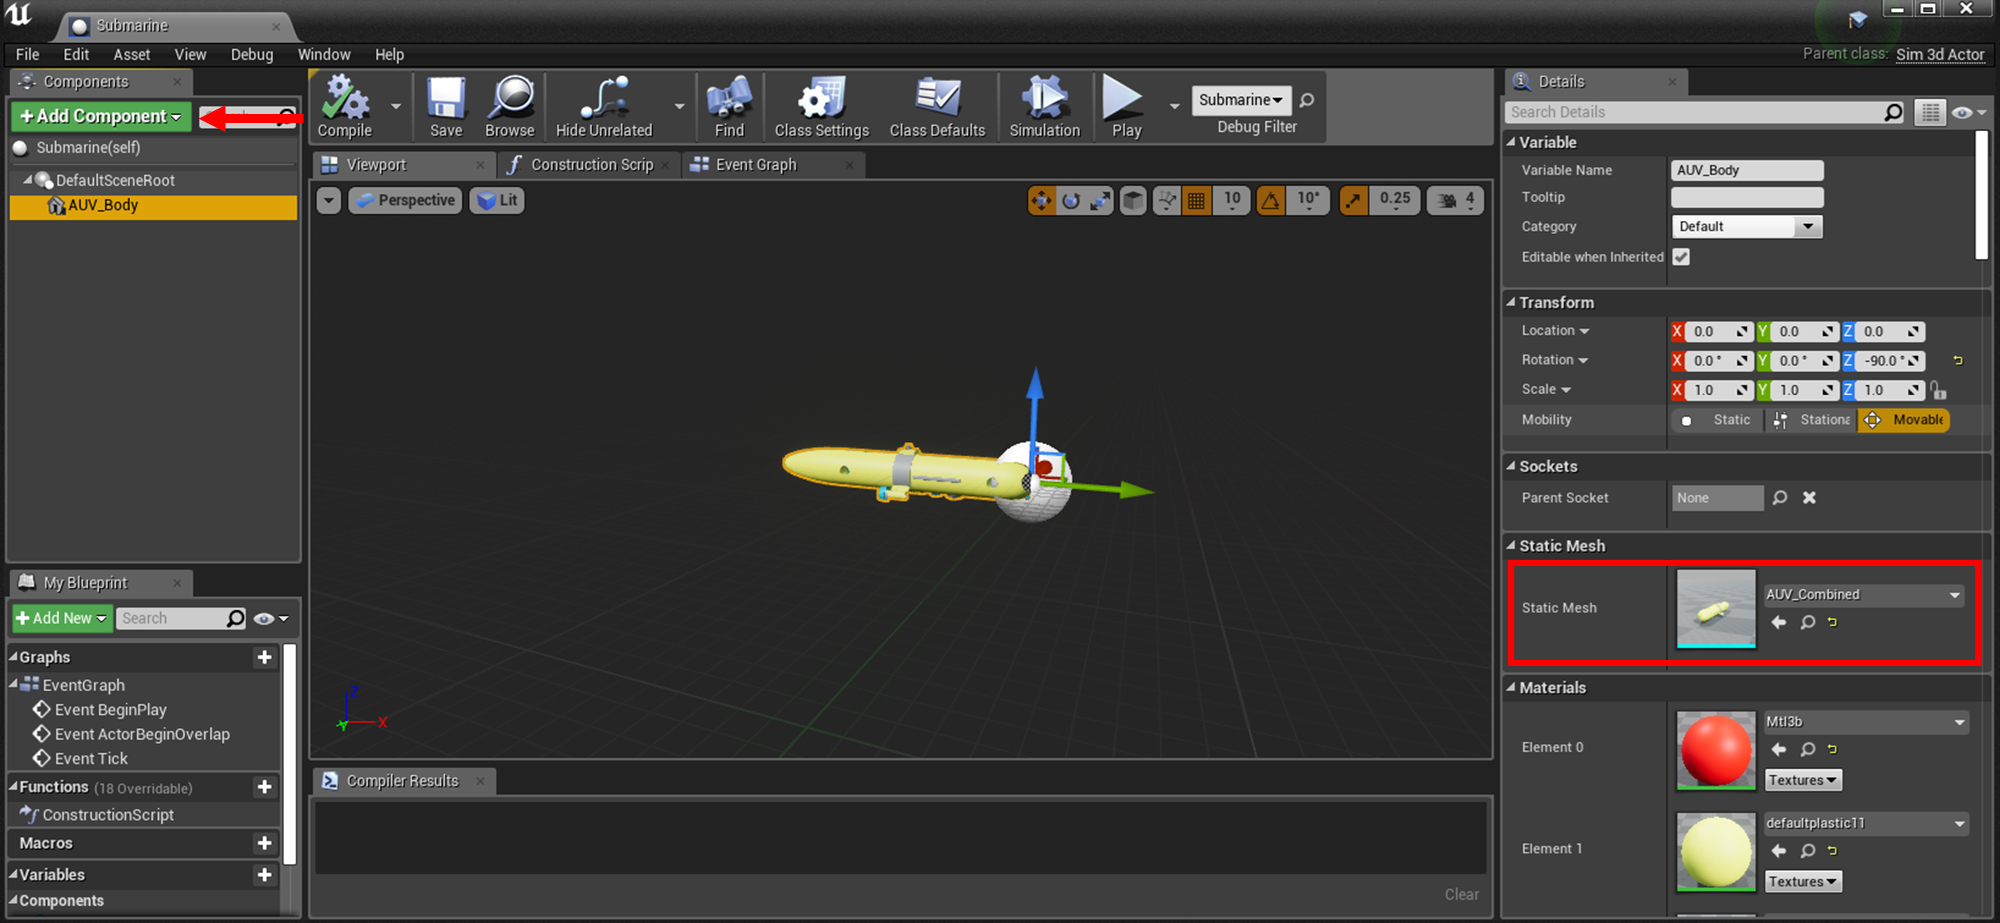

These mesh components may be ingested as '.fbx' files into Unreal  Engine or 'Migrated' using the asset migration process from  a different Unreal Engine 4 project. You can control these custom actors with the '[Simulation 3d Actor Transform Get](matlab:web(fullfile(docroot, 'vdynblks/ref/simulation3dactortransformget.html')))' and '[Simulation 3d Actor Transform Set](matlab:web(fullfile(docroot, 'vdynblks/ref/simulation3dactortransformset.html')))' blocks. These blocks can be used to set the world position of the agent based on the physical plant model behavior in Simulink and get the current pose of the actor in the world for feedback control strategies. 

Next, we want to retrieve data from simulated sensors in the environment. Dragging the sensors into the environment and placing them on the actor according to these instructions will allow you to [instrument your actor](matlab:web(fullfile(docroot, 'vdynblks/ug/place-cameras-on-actors-in-the-unreal-editor.html'))). The sensor type and the 'Sensor Identification Number' block parameter for sensor blocks such as Cameras, Lidars, etc. will determine the 'Actor Tag' which must be set in Unreal Engine. 

This 'Actor Tag' can be set by clicking the "+" icon and typing in the formula <SensorType><Sensor Identification Number>. For example, in the model provided the sensor type is "Lidar" and the Identification is 2, so the tag is "Lidar2", and the Camera has Sensor Identification Number 1, so the tag in Unreal Engine is "Camera1". 

## Run the model

% With everything set up, we can now co-simulate the Unreal Engine Scene
% with Simulink driving the underlying physics simulation. 

 sim("AUV_UE4_Visualization")

% To enable co-simulation, you should modify the 'scene source' in the
% Simulation 3d Scene Configuration block to 'editor' and point it to the
% provided '.uproject' file. 

`Copyright 2020 The MathWorks Inc.`